## Exercise 1

clear
syms x1 x2 xe
g = @(x1,x2,x3) 4*x1 + 2*x2 + x3

g = function_handle with value:
    @(x1,x2,x3)4*x1+2*x2+x3



A = [   1 0 0 1 0 0 0;
        4 1 0 0 1 0 0;
        8 4 1 0 0 1 0];
b = [ 1;4;16];
c = -[4;2;1; 0; 0; 0; -1 ];
v = [4;5;6];
simplex(c,A,b,v,1)

 
Initial tableau:
  Columns 1 through 2

       1              0       
       4              1       
       8              4       
      -4             -2       

  Columns 3 through 4

       0              1       
       0              0       
       1              0       
      -1              0       

  Columns 5 through 6

       0              0       
       1              0       
       0              1       
       0              0       

  Columns 7 through 8

       0              1       
       0              4       
       0             16       
       1              0       

Pivot point:
       1              1       

New tableau:
  Columns 1 through 2

       1              0       
       0              1       
       0              4       
       0             -2       

  Columns 3 through 4

       0              1       
       0             -4       
       1             -8       
      -1              4       

  Columns 5 through 6

       0    

ans =        0       
       0       
      16       
       1       
       4       
       0       
       0       


## a)

Initial table is:

Initial tableau:

       1              0              0              1              0              0              0              1       

       4              1              0              0              1              0              0              4       

       8              4              1              0              0              1              0             16       

      -4             -2             -1              0              0              0              1              0  

From last collumn we pick most negative value (In that case it is -4 which is first collumn)

We calculare ratio for this collumns so:

1/1

ans =        1       


4/4

ans =        1       


16/8

ans =        2       


From results we pick lowest value which has row 1 and 2 (value = 1) we pick one and that will be our pivot.

First operation is to change our pivot (first row) to value 1 which is already done we can skip

Second operation is to make Row 2 column 1 - 0 so: -4R1 + R2 -> R2

Third operation is to make Row 3 column 2 - 0 so: -8R1 + R3 -> R3

Forth Operation is to make our Last row collumn 1 = 0 so: 4R1 + R4 -> R4

Result table:

       1              0              0              1              0              0              0              1       

       0              1              0             -4              1              0              0              0       

       0              4              1             -8              0              1              0              8       

       0             -2             -1              4              0              0              1              4     

Maximum is 16 !

### b)

Dual problem from Maximization will be minimization  

c = -[1;4;16];

Dual problem:

Minimize            y1 + 4y2 + 16y3

Subject to:         y1 + 4y2 + 8y3 => 4

                          y2 + 4y3 => 2

                          y3 =>1

#### Exercise 2

clear
syms x1 x2
g = @(x1,x2) x1^3 - 3*x1 -x2^2

g = function_handle with value:
    @(x1,x2)x1^3-3*x1-x2^2



%%a

df1_x1 = diff(g,x1);
df1_x2 = diff(g,x2);
Df = [df1_x1 df1_x2]

$$Df = \left(\begin{array}{cc} 3\,{x_{1}}^{2}-3 & -2\,x_{2} \end{array}\right)$$

gradient = Df'

$$gradient = \left(\begin{array}{c} 3\,{\bar{x_{1}}}^{2}-3\\ -2\,\bar{x_{2}} \end{array}\right)$$

gradient = matlabFunction(gradient);

[x1,x2] = solve(gradient(x1,x2)==0,x1,x2)

$$x1 = \left(\begin{array}{c} -1\\ 1 \end{array}\right)$$

$$x2 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Critical points are [-1 1] and [0 0] with values 1 and 0

b)

g(-1,1)

ans =        1       


g(0,0)

ans =        0       



clear;
syms x1 x2;
%c)
f = @(x1,x2) (x1 - 2)^2 + (x2 - 1)^2;
h = @(x1,x2) (x1 - 1)^2 + (x2 + 2)^2 -1;

%Lagrange

syms lambda
l = f(x1,x2)+lambda*h;

%Calculate derivatives
dlx1 = diff(l,x1);
dlx2 = diff(l,x2);
dll = diff(l,lambda);

%Main function to get points
syms x1 x2 lambda
[x1, x2, lambda] = solve(dlx1==0,dlx2==0,dll==0, x1, x2, lambda)

$$x1 = \left(\begin{array}{c} \frac{\sqrt{10}}{10}+1\\ 1-\frac{\sqrt{10}}{10} \end{array}\right)$$

$$x2 = \left(\begin{array}{c} \frac{3\,\sqrt{10}}{10}-2\\ -\frac{3\,\sqrt{10}}{10}-2 \end{array}\right)$$

$$lambda = \left(\begin{array}{c} \sqrt{10}-1\\ -\sqrt{10}-1 \end{array}\right)$$


%Save points to variables
x1 = [sqrt(10)/10+1 ; 3*sqrt(10)/10 - 2 ]

x1 =      949/721   
    -758/721   


x2 = [1-sqrt(10)/10 ; -3*sqrt(10)/10 - 2 ]

x2 =      493/721   
   -2126/721   



%Insert points into function to get values
f(x1(1),x1(2))

ans =     6569/1405  


f(x2(1),x2(2))

ans =     1975/114   


Point x2 is minimum with value of 1975/114

Point x1 is maximum with value of 6569/1405

# Exercise 3

a) No

b) No

c)

d) Searching for optimal solution in a finite set of potentional solutions.

Examples: Sellers problem (From internet)

A sales rep sells 12 types of vacuum cleaners. During one day he has to visit 9 customers by car to demonstrate his products. 

Problem 1: What is the shortest route? ("Traveling Salesman problem") 

Problem 2: All the 12 models do not fit in the car. What models to take? ("Knapsack Problem") Given data: 

- distances between locations 

- trunk size of the car and sizes of models 

- expected profit / utility for demonstrating each model

e) quasi-newton uses approximate of hessian which is "cheaper" to caluclate than Newton which use exact hessian.

#### f) (i) 

Best way to develop representation us by use of bits because the ycan be very easily mutated by just switching them. we have integers to 7 which we can fit into 3 bits but we have also "+/-" mark hre so we can add bit for that (first bit) so we have total of 4 bits

for example: (3,-2) => [0011,1001] where first but is 0 for + and 1 for - other 3 bits are actual number

#### (ii)

**Matrix of current grid with kinda simulated heat values could be created for this exercise but no time. same as for exercise (f-iii)**

Goal is to maximize heat for givent 2 points from all possible points. 

o = @(x1,x2) ....

#### (iii)

Function should return heat of current position (Higher == better)

f = @(x1,x2) return current heat

#### (IV)

Parent 1:  [0011,1001]

Parrent 2:  [0001,1111]

Crossover in the middle:

Child: [0011,1111]

# Exercise 4

% Given:
clear;
c1 = [  0 1;
        1 1]

c1 =        0              1       
       1              1       


[k,NC(1)] = size(c1);

c2 = [ 3 3 4;
       1 2 2]

c2 =        3              3              4       
       1              2              2       


[k,NC(2)] = size(c2);

X = [1 3 2;
    2 0 1]

X =        1              3              2       
       2              0              1       


[k,NX] = size(X);
[k,NX] = size(X);
K=2

K =        2       





%% a) NC
% Calculate class means along each dimension
mean1 = mean(c1,2)

mean1 =        1/2     
       1       


mean2 = mean(c2,2)

mean2 =       10/3     
       5/3     


% Calculate euclidean distances from class means
x_c1_dist = sqrt(sum((X-mean1)'.^2, 2))';    % Norm of each column
x_c2_dist = sqrt(sum((X-mean2)'.^2, 2))';    % Norm of each column
nc_dist = [x_c1_dist; x_c2_dist];

% Classify samples to the nearest centroid
[nc_min_dist,nc_classification] = min(nc_dist);
nc_classification

nc_classification =        1              2              2       



%% b) NNC
% Calculate the distance to all class samples
nn_dist = zeros(2,NX);
for i=1:NX
    % Calculate distance to samples of class 1  
    dist_c1 = []; 
    for j=1:NC(1)
       dist_c1(j) = norm(X(:,i)-c1(:,j));
    end
    % Find the nearest class 1 neighbor
    nn_dist(1,i) = min(dist_c1);
    
    % Calculate distance to samples of class 2  
    dist_c2 = []; 
    for j=1:NC(2)
       dist_c2(j) = norm(X(:,i)-c2(:,j));
    end
    % Find the nearest class 2 neighbor
    nn_dist(2,i) = min(dist_c2);
end
nn_dist;

% Classify samples to the nearest neighbor
[nn_min_dist,nn_classification] = min(nn_dist);
nn_classification

nn_classification =        1              2              1       


## c) byas-based

[k,N(1)] = size(c1);
[k,N(2)] = size(c2);
a_priori = [];
for i=1:K
   a_priori_prob(i) = N(i)/sum(N); 
end
a_priori_prob;
% Calculate class means along each dimension
mean1 = [mean(c1(1,:));
        mean(c1(2,:))];

mean2 = [mean(c2(1,:));
        mean(c2(2,:))];
% Calculate euclidean distances from class means
x_c1_dist = vecnorm(X-mean1);
x_c2_dist = vecnorm(X-mean2);

% Calculate the class-conditional probability density
p_x_given_c1 = x_c1_dist ./ (x_c1_dist + x_c2_dist);
p_x_given_c2 = x_c2_dist ./ (x_c1_dist + x_c2_dist);
  
p_x_given_c = [p_x_given_c1;
               p_x_given_c2];
% Multiplying the a priori probability and the posteriori distribution element wise
P_c_given_x = a_priori_prob' .* p_x_given_c;

% Compare probabilties by evaluating difference
diff = P_c_given_x(1,:) - P_c_given_x(2,:);

class = zeros(1,NX);
for i=1:NX
    if diff(i) > 0
       class(i) = 1; 
    elseif diff(i) < 0
        class(i) = 2;
    else
        class(i) = 0;   % Classes are equally likely
    end
end
class

class =        2              1              2       


`nc_classification = ``1×3`

`       1              2              2       `

`nn_classification = ``1×3`

`       1              2              1       `

`class = ``1×3`

`       2              1              2       `

#### `d)`

`From output classification we can see that classifications are different for each of the classifier.`

`NC and NN classifiers missmatched only in one of the test point while bayes based classifier classified data odifferently.`

`This can be also caused because of small train data-set`

# `Exercise 5`

#### `a)`

`NO - LDA is preffered to use for more than 2 classes.`

#### `b) `

#### `c)`

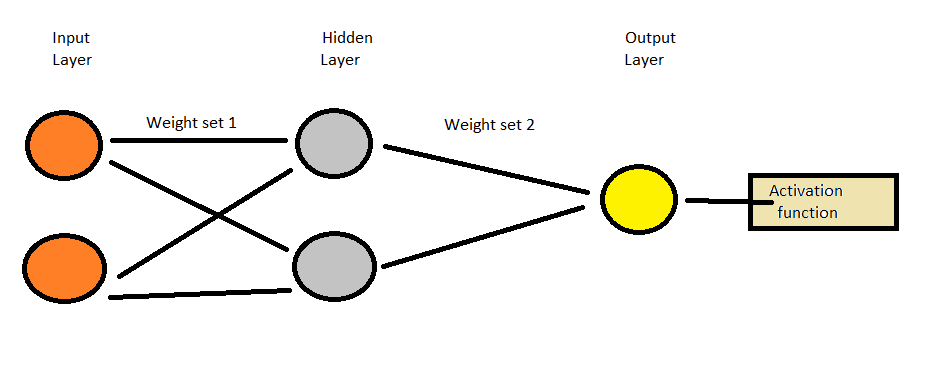

sigmoid activation function:

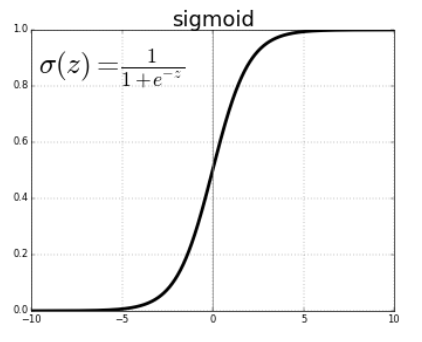

#### d) Cluster is not linear

# Exercise 6

%a) no train data set ?

X = [3;7;8;9]; %test data



%b) but not trained classifier (example how to calculate risk)
loss = [0 0.3;
        0.2 0]

loss =        0              3/10    
       1/5            0       


           
risk = loss*P_c_given_x

risk =      152/1245       589/8456       199/2218  
     237/9208       169/3446       155/3863  



class = zeros(1,NX);
for i=1:NX
    if risk(1,i) < risk(2,i)
       class(i) = 1; 
    elseif risk(1,i) > risk(2,i)
        class(i) = 2;
    else
        class(i) = 0;   % Classes are equally likely
    end
end
class

class =        2              2              2       
